# Example of How to Run the Lap Sim

## Step 1 : Load in Car

addpath(genpath(pwd)) % add all subfolders to matlab path

veh = load('01 Vehicles/StagVIII.mat');

### Editing Vehicle Parameters

The vehicle data is contained in the structure "veh". To edit the data, simply edit the values in the structure as shown below.

veh.CdA = 1.996697;
veh.ClA = 4.22063;
veh.SprocRatio = 2.5;

### Vehicle parameters are :

Note: for the Stag X version of the point mass sim, gear/shifting parameters have been removed. Please see the previous matlab code to simulate a gearbox.

- CdA : Vehicle Drag coefficent (inc. frontal area)

- ClA : Vehicle Lift coefficent (inc. frontal area)

- GFLat : Lateral grip multiplier applied to tyre data

- GFLong : Longitudinal grip multiplier applied to tyre data

- GGVFactor : Factor to control how close to friction "circle" or friction "diamond" sim will go in combined cases. 1 is pure friction circle (max performance).

- MaxRPM : Max allowable motor RPM

- RollRad : Rolling radius of tyre

- SprocRatio : Ratio between motor speed and wheel speed

- Trq : Name of sheet in motor_torque_curves.xlsx with torque vs rpm lookup table. Can also be lookup table directly specified as nx2 matrix

- Tyres : 2x1 cell array of strings containing name of mat files for lateral and longitudinal tyre lookup tables (normalised force vs vertical load)

- WDist : Percentage of total vertical load acting on 'tyre' during acceleration phase. Used to model rear wheel drive

- mass : Total vehicle mass, including driver

- DriveEfficiency : Scaling factor applied to power unit torque before it "reaches" the wheels

## Step 2 : Load in Track

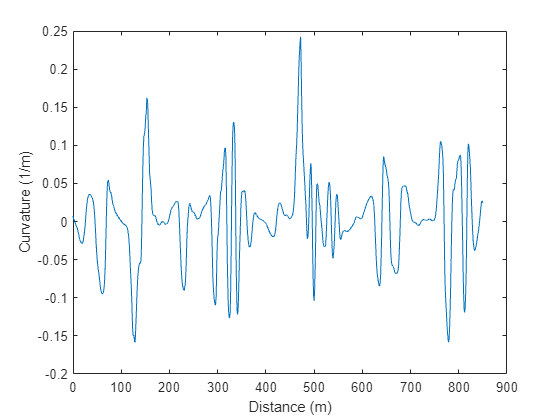

track = load('00 Tracks/FSUK_Sprint_MP.mat');

% The track structure must contain distance and curvature values
plot(track.Distance, track.Curvature)
ylabel('Curvature (1/m)')
xlabel('Distance (m)')

### Generate Track Map

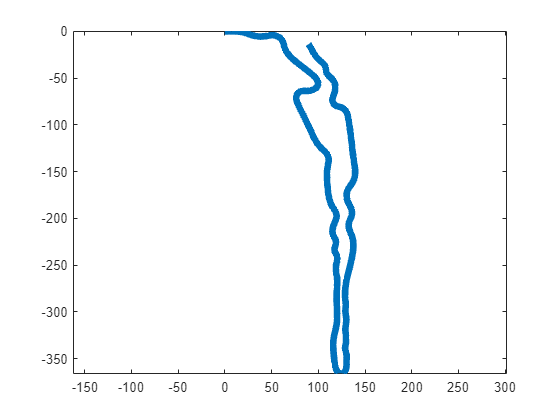

% It may also optionally contain X and Y values
[x,y] = fnCoordPlot('00 Tracks/FSUK_Sprint_MP.mat');

## Step 3 : Run Lap Sim

The options structure helps to configure the lap sim. Feel free to play around with turning these options on an off.

### Options parameters are:

- PlotGGV : (default = 0, no plot) - Plot the GGV diagram for the inputed vehicle.

- PlotTrqCurve : (default = 0, no plot) - Plot the toruqe curve.

- BOutputLog : (default = 1, output log to cmd window) - Output log to the cmd window.

- BPlotProgress : (default = 0, don't plot) - Plots the sim's progress in terms of apexs found and current fastest speed around the track.

- StartSpeed : (default = 0) - The speed from which to start from.

- tol : (default = 10%) - Percentage speed by which the solver can go past the theoretical max speed.

- LiftOffPercent : (default = 0%) - Percentage of end of straight lift off.

options.PlotGGV = 0;
options.BOutputLog = 0; % don't output log to cmd window
options.BPlotProgress = 0;

result = runLapSim(veh,track,options);

## Step 4: Explaining the Lap Sim

The simulation can be visualised using the option BPlotProgress. 

The lap time simulation for this lap sim uses the forward/reverse method *(not an official name):*

- The GGV diagram is calculated to find the limits of the provided vehicle

- Using the GGV the maximum speed at any point is found (green line) and the apecies are calculated

- Braking distance from the max speed to the maximum apex speed is calculated (red line)

- Acceleration from the previous apex to the max speed is calculated (blue line)

- The crossover point of these lines is the braking point for a corner and the lowest speeds are added to find the laptime

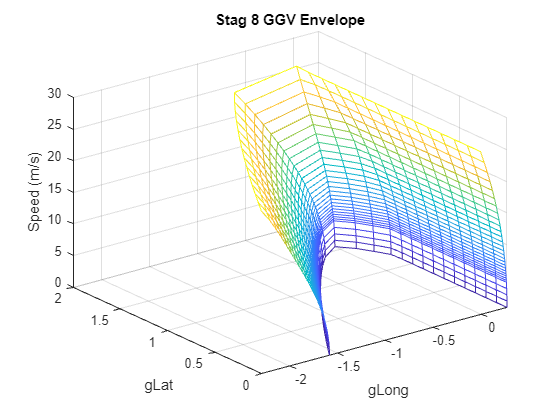

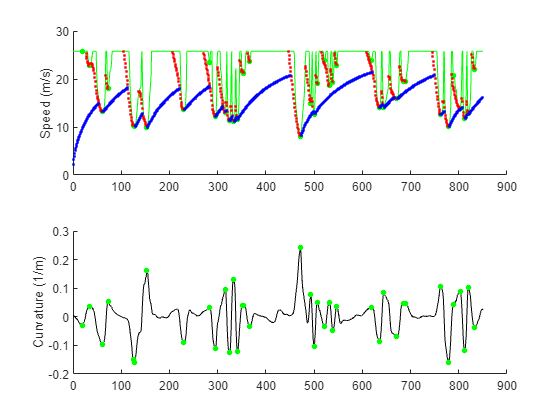

options.PlotGGV = 1;
options.BPlotProgress = 1; % plot sim's progress
% NOTE: this will take a while but it is useful to visualise!

result = runLapSim(veh,track,options);

## Step 5 : Visualise Results

fprintf('Lap Time : %.2f seconds\n', result.metrics.LapTime)

Lap Time : 59.29 seconds


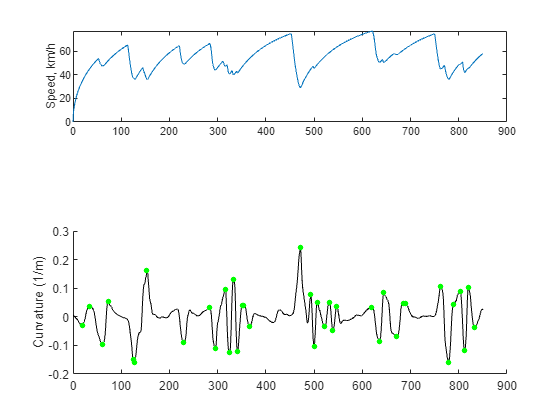

subplot(3,1,1)
plot(result.channels.dist,result.channels.vkmh)
ylabel('Speed, km/h')

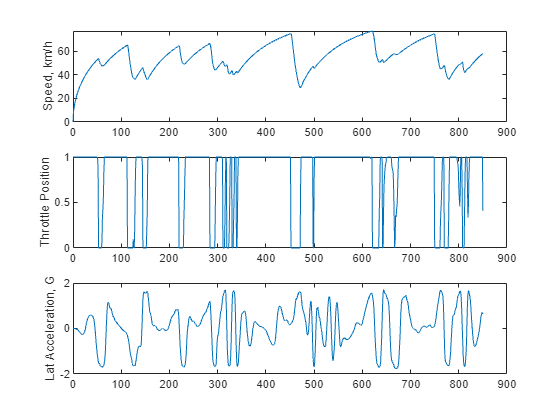


subplot(3,1,2)
plot(result.channels.dist,result.channels.Throttle)
ylabel('Throttle Position')

subplot(3,1,3)
plot(result.channels.dist,result.channels.gLat)
ylabel('Lat Acceleration, G')

fprintf('The Following Metrics are available :')

The Following Metrics are available :

chns = fields(result.metrics);
for i = 1:length(chns)
    fprintf('%s\n',chns{i})
end

LapTime
SolutionTime
PUEnergyOUT_MJ
AvgThrottle
vMax


fprintf('The Following Channels are available :')

The Following Channels are available :

chns = fields(result.channels);
for i = 1:length(chns)
    fprintf('%s\n',chns{i})
end

speed
vkmh
gLongRAW
dist
curvature
time
gLat
gLong
FDrag
FLift
FTractive
FTractPos
FTractNeg
PTractive
PTractPos
PTractNeg
ETractive
ETractPos
ETractNeg
TrqPUAvail
TrqPUUsed
RPM
PPU
EPU
Throttle
